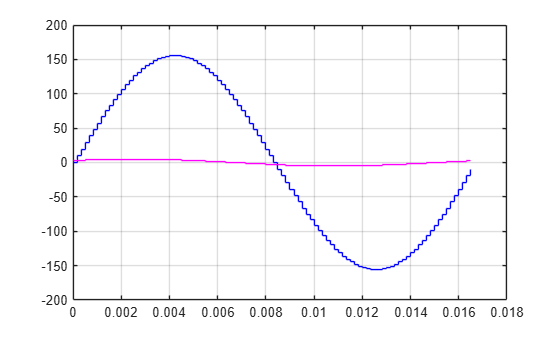

clear;                                                                      % Limpa as variaveis
clc;
close all;

% Limpa a tela

N=100;                                                                       % Serah N=10 amostras/ciclo
freq=60;                                                                    % A frequencia dos sinais de tensao e corrente serah de 60,0 Hz (rede eletrica)
Av = 155.563;                                                               % A amplitude de pico do sinal de tensão serah de 155,563 V, que equivale a 110 V (rms)
Ai = 5.0;                                                                   % A amplitude de pico do sinal de corrente serah de 5,0 A, que equivale a 3,53 A (rms)
defasagem=36.36;                                                            % A defasagem da corrente serah de 36.36 graus

n = zeros(1,N);                                                             % Criacao do vetor de tempo discreto "n"
t = zeros(1,N);                                                             % Criacao do vetor de tempo continuo "t"
Tensao = zeros(1,N);                                                        % Criacao do vetor do sinal de tensao instantanea
Corrente = zeros(1,N);                                                      % Criacao do vetor do sinal de corrente instantanea
Pot_inst = zeros(1,N);                                                      % Criacao do vetor do sinal de potencia instantanea
Tensao_RMS = 0;                                                             % Variavel para armazenar o valor RMS da tensao
Corrente_RMS = 0;                                                           % Variavel para armazenar o valor RMS da corrente
P_ativa = 0;                                                                % Variavel para armazenar o valor da potencia ativa
P_parente = 0;                                                              % Variavel para armazenar o valor da potencia aparente
Fator_De_Potencia = 0;                                                      % Variavel para armazenar o valor do fator de potencia

Periodo = 1/freq;                                                           % Calcula o periodo do sinal (tempo de 1 ciclo)
dt = Periodo/N;                                                             % Calcula o intervalo de amostragem

for i=0:1:(N-1)                                                             % Inicializa o vetor de tempo discreto "n" e de tempo continuo "t"
    n(i+1) = i;
    t(i+1) = n(i+1)*dt;
end

Tensao = Av*sin(2*pi*freq*t);                                               % Cria o vetor de um ciclo do sinal de tensao instantanea
stairs(t,Tensao,"b");                                                         % Plota para ver o sinal na cor azul

hold on;
grid on;

% Mantem o grafico para plotar um nome sobre o antigo

Corrente = Ai*sin(2*pi*freq*t+(pi*defasagem/180));                          % Cria o vetor de um ciclo do sinal de corrente instantanea defasada
stairs(t,Corrente,"m");                                                           % Plota para ver o sinal, sobre o antigo e na cor vermelha
                                                                      % Dah uma pausa para ver ateh apertar qualquer tecla

hold off;                                                                   % Libera o grafico para plotar outros

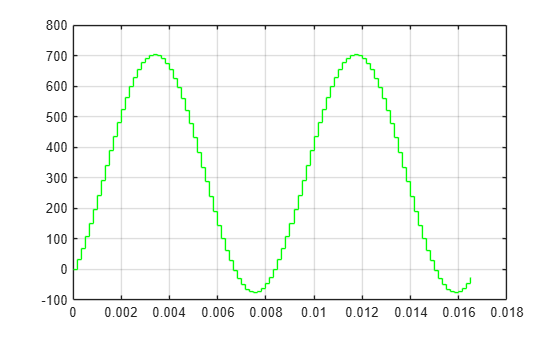


for i=0:1:(N-1)                                                             % Calcula o vetor do sinal de potencia instantanea
    Pot_inst(i+1) = Tensao(i+1)*Corrente(i+1);
end
stairs(t,Pot_inst,"g");                                                       % Plota para ver o sinal na cor verde
grid on;



for i=0:1:(N-1)                                                             % Calcula o o valor RMS do sinal de tensao
    Tensao_RMS = Tensao_RMS + Tensao(i+1)^2;
end
Tensao_RMS = Tensao_RMS/N;
Tensao_RMS = sqrt(Tensao_RMS);

for i=0:1:(N-1)                                                             % Calcula o valor RMS do sinal de corrente
    Corrente_RMS = Corrente_RMS + Corrente(i+1)^2;
end
Corrente_RMS = Corrente_RMS/N;
Corrente_RMS = sqrt(Corrente_RMS);

P_parente = Tensao_RMS*Corrente_RMS;                                        % Calcula o valor da potencia aparente

for i=0:1:(N-1)                                                             % Calcula o valor da potencia ativa
    P_ativa = P_ativa + Pot_inst(i+1);
end
P_ativa = P_ativa/N;

Fator_De_Potencia = P_ativa/P_parente;                                      % Calcula o valor da potencia aparente

% Exibe os resultados:
Tensao_RMS

Tensao_RMS = 109.9997

Corrente_RMS

Corrente_RMS = 3.5355

P_ativa

P_ativa = 313.1903

P_parente

P_parente = 388.9075

defasagem

defasagem = 36.3600

Fator_De_Potencia

Fator_De_Potencia = 0.8053